# DEMO - Distributed Grey-box Model Building Identification (with the use of the EnergyPlus)

This is a demo example of the Distributed Grey-box Model Building Identification algorithm [1]. Based on input data (measured outside temperature, zone temperatures and thermal powers) generated by EnergyPlus model of the Fenix building and provided by EnergyPlus Co-simulation Toolbox [2] a grey-box model of this building is identified in a distributive manner.

© (2020) Created by Tomas Bäumelt - Czech Technical University in Prague, University Centre for Energy Efficient Buildings

E-mail contact: [tomas.baumelt@cvut.cz](mailto:tomas.baumelt@cvut.cz)

## Requirements:

- Matlab

- Simulink

- EnergyPlus Co-simulation Toolbox [2]

- Control System Toolbox

- System Identification Toolbox  

- Optimization Toolbox

- Symbolic Math Toolbox

[1] - [Control Engineering Practice: Distributed agent-based building grey-box model identification](https://authors.elsevier.com/tracking/article/details.do?aid=104427&jid=CONPRA&surname=B%C3%A4umelt)

[2] - [Mathworks File Exchange: EnergyPlus Co-simulation Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/69074-energyplus-co-simulation-toolbox)

## Init paths etc.

clearvars, clc, close all % clear workspace and command window and close everything
addpath(genpath('../')); % generate pathes to all necessary folders and add them to the matlab path
% make a folder for temporary files
cd ./EnergyPlus_model/
tmp_folder = 'tmp';
if exist(tmp_folder,'dir')~=7
    mkdir(tmp_folder);
end
addpath(tmp_folder);
cd ./tmp

## Identification data generation (by simulation)

### Zone temperature setpoints generation

PRNS = 1; % PseudoRandom Number Sequence generator (0 ~ OFF, 1 ~ ON)
% for generating zone temperature setpoints

Ts_ep = 10*60; % [s] - sampling period for the data which serve as the EnergyPlus input data
% zone temperature setpoints if PRNS is not used
main_seq = [19 26 32 24 20;
            25 32 24 28 22;
            22 33 26 21 28;
            27 21 32 22 27];
Ts_rand_temp = [4 40]*3600; % [s] - time of steady temperature setpoint
min_temp = [15 -3]; % [degC] - minimal temperature
max_temp = [30 3]; % [degC] - maximal temperature
temp_dc = [22 0]; % [deg C] - mean value of temperature setpoint
temp_noise_std = [5 2]; % [degC] - standard deviation of temperature setpoint used in PRNS
seed_1 = [09858; % initial seeds for PRNS
        86502;
        98405;
        84858];
seed_2 = [65148; % initial seeds for PRNS
        01366;
        76165;
        61506];   

### Simulation settings

sim_days = 8; % length of simulation in days
sim_time = sim_days*24*3600; % [s] - simulation time
model = 'mlep_fenix_direct_hf_ctrl'; % name of the simulated model

% SIMULINK simulation
disp('Simulating EnergyPlus model...');

Simulating EnergyPlus model...


load_system(model);
sim(model,sim_time);
% At the end of the simulation the data (arrays): 'u_hf', 'u_cf', 'y', 'T_out'
% are exported to the base workspace
Ts = epOutbus.Elements(1).SampleTime; % [s] - sampling period of the data coming from EP
u_hx = u_hf - u_cf; % [kW] - thermal power of heat exchangers

## Distributed building identification process

### Global (master) identification problem settings

max_iter = 50; % maximal number of overall (global) iterations
prec = 1e-2; % value of the consistency constraint residual (~threshold)

### Local identification problem settings

step_size = 0.0008; % step size of the local gradient problem
var_step = 1; % 0 - fixed step, 1 - variable step of the local gradient problem
% For details, see the class Coordinator.m

### Grey-box model settings

useZoneC2 = 1; % 0 - one-capacity zone model, 1 - two-capacity zone model
scale = [5e4 5e6 100 80 20]; % Cz, Cs, UAs, UAwi, UAwo - scale of identified parameters
% For more detail, see the class BuildingID.m

% adjacency matrix of a 4-zone building
adjMatrix = [0     1     1     0;
             1     0     0     1;
             1     0     0     1;
             0     1     1     0];
adjacencyToOutside = [1 1 1 1]; % logical vector of zones' adjacency to outside
HEXsInZones = [1 1 1 1]; % number of heat exchangers in zones
solarGains = [1 1 1 1]; % number of solar gains in zones

### Distributed identification run

% Create fundamental instance of the BuildingID class for the identification process
B = BuildingID(adjMatrix,adjacencyToOutside,HEXsInZones,solarGains,useZoneC2,scale);

% Create zone agents and coordinators
B.buildIdProblem;

% Load ID data and assign them to the zones
B.loadData(y,u_hx,u_sg,T_out,Ts);

% Start and run overall building identification
% ID info is printed out in the command window after every global iteration
B.runIdentification(prec,max_iter,step_size,var_step);

Iteration 1 done. Consistency constraint residual: 0.32834.
ZoneC2 1:
Cz1: 10520.9848
Cs1: 24949496.0129
Us1: 14.2389
alp1: 0.031682
bet1: 0.98437
Usf1: 0.99995
U12: 71.9596      57.8425
U13: 61.557      47.7231
U10: 42.9229
ZoneC2 2:
Cz2: 8327.7155
Cs2: 12291331.3923
Us2: 14.4932
alp2: 0.061841
bet2: 0.99976
Usf2: 0.99995
U12: 71.9596      57.8425
U24: 29.9858      12.7272
U20: 18.8914
ZoneC2 3:
Cz3: 9636.0472
Cs3: 10050567.9365
Us3: 14.6504
alp3: 0.058552
bet3: 0.99962
Usf3: 0.99998
U13: 61.557      47.7231
U34: 64.6564      63.4541
U30: 27.4382
ZoneC2 4:
Cz4: 11685.9019
Cs4: 37511288.8176
Us4: 14.7184
alp4: 0.033956
bet4: 0.99959
Usf4: 0.99992
U24: 29.9858      12.7272
U34: 64.6564      63.4541
U40: 40.5244
Iteration 2 done. Consistency constraint residual: 0.7038.
ZoneC2 1:
Cz1: 38969.0198
Cs1: 27697206.8136
Us1: 53.9933
alp1: 0.12113
bet1: 0.91297
Usf1: 0.99996
U12: 38.375      73.4017
U13: 43.1815      53.7553
U10: 41.5167
ZoneC2 2:
Cz2: 9418.29
Cs2: 12671631.9311
Us2: 16.7829
al

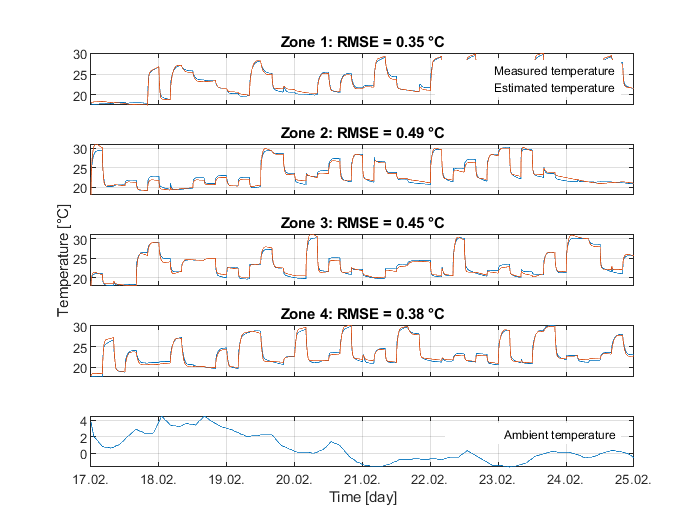

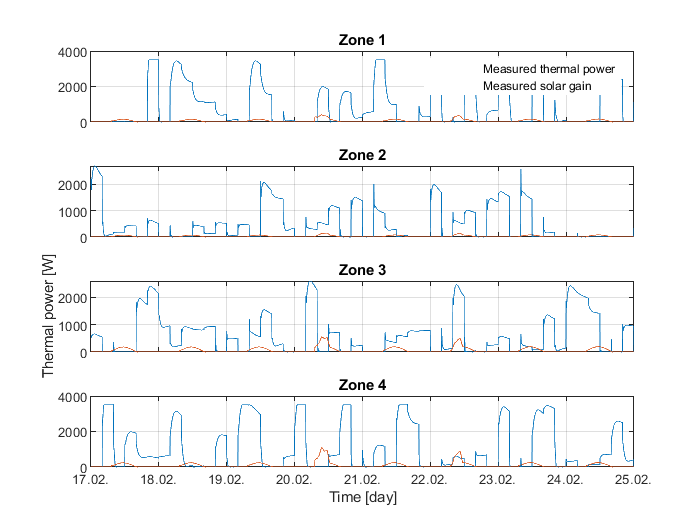

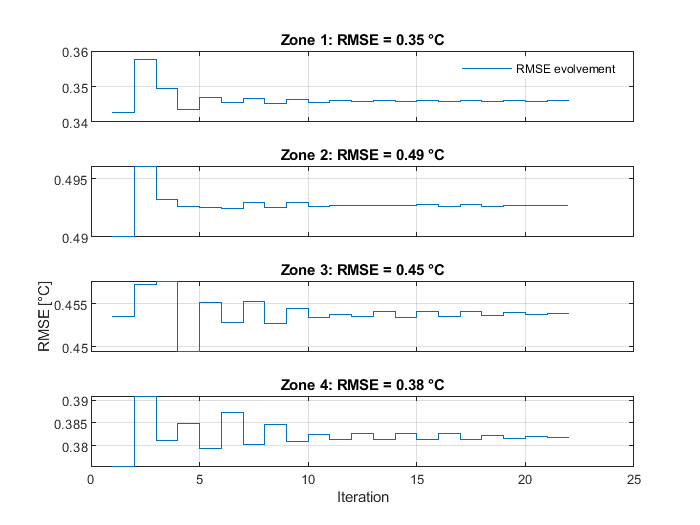

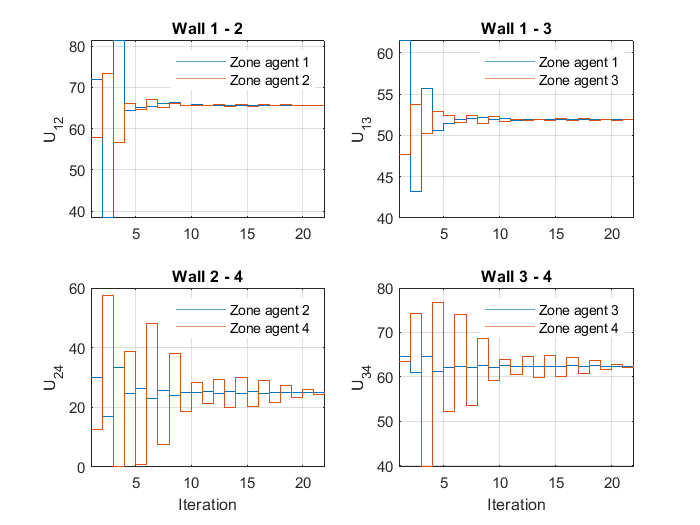

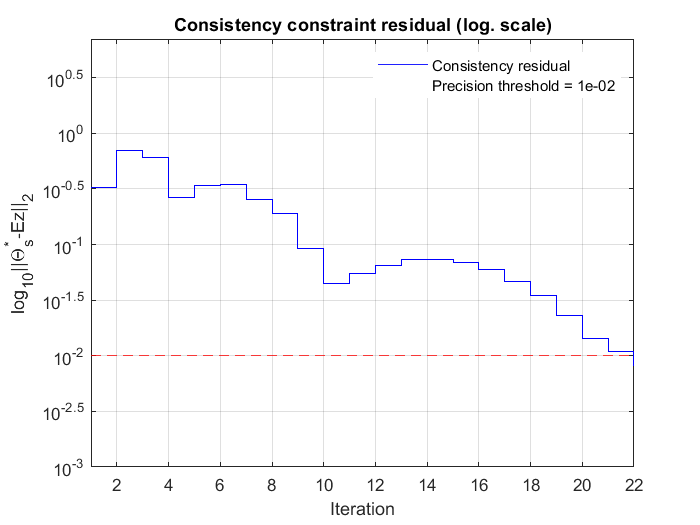


% Plot results of the building identification 
B.analyzeResults;

cd ../../ % return to the original folder